Let's read in the digital disc phantom.

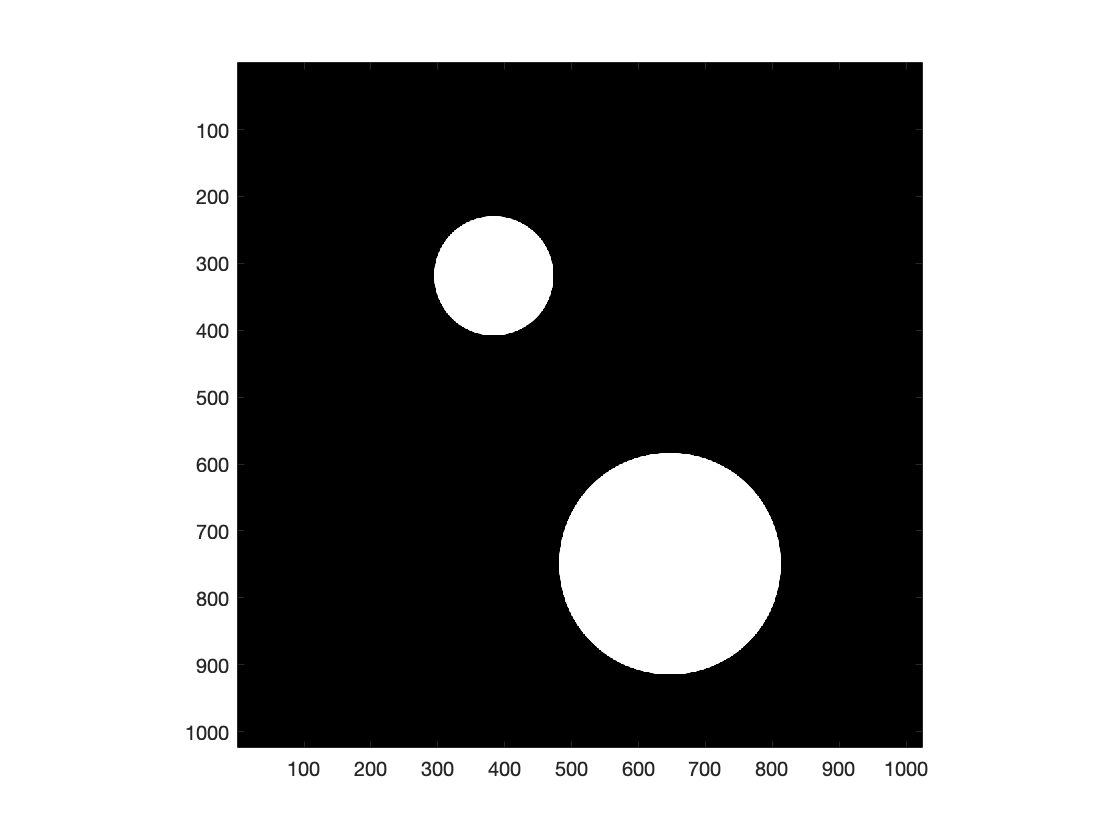

% Read in the phantom image
ph  = double(imread('data/TwoDots.png'));
% Record the size of the (square) image
[row,col] = size(ph);
Nph = row;
% Make sure there are no negative pixels
ph  = max(0,ph);
% Normalize pixel values to interval [0,1]
ph  = ph/max(ph(:));
% Take a look
figure
imagesc(ph)
colormap gray
axis square

Now that we have the phantom available, we can simulate tomographic data using the command radon.m

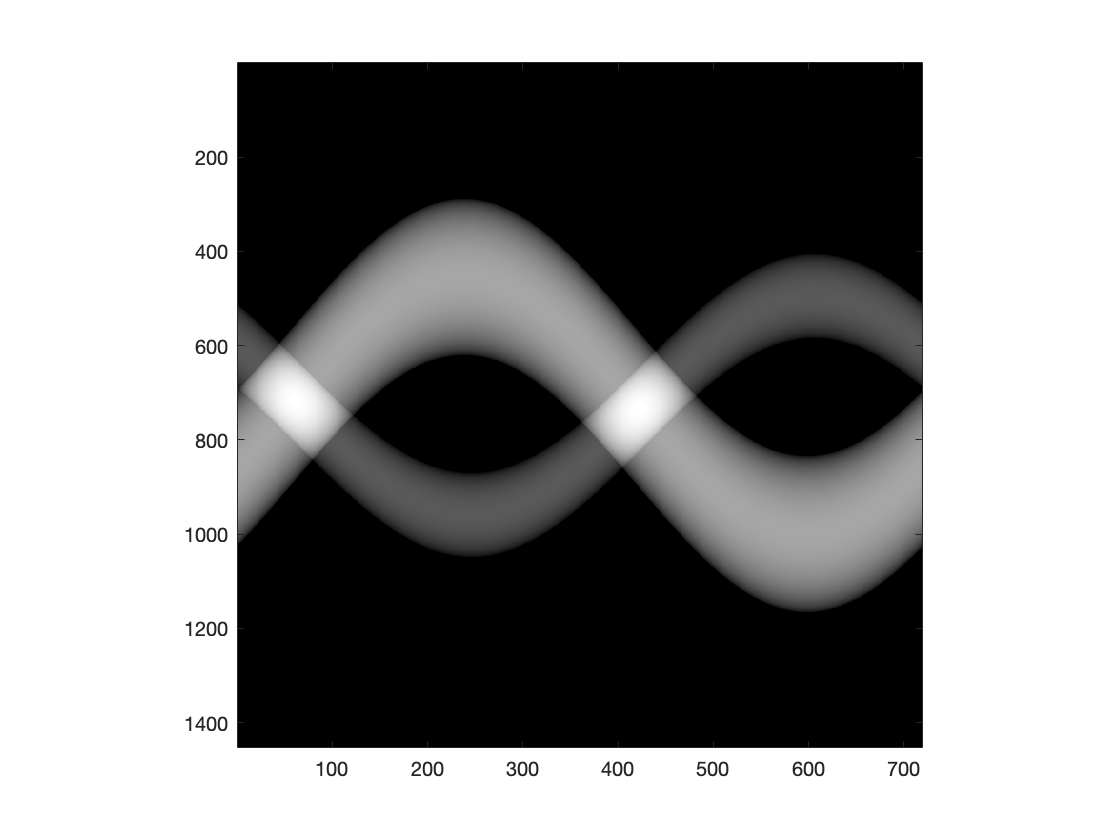

% Choose angles of X-rays in the 
% parallel-beam Radon transform. 
% We go for a full 360 degree measurement 
% with half degree angular step. 
angvec = 1:.5:360;
% Calculate the sinogram 
sinogram = radon(ph,angvec);
% Take a look
figure
imagesc(sinogram)
colormap gray
axis square

Time to reconstruct! We can implement filtered back-projection using the iradon.m command. We give Nph as an argument to ensure that the output has the same size than the original phantom. 

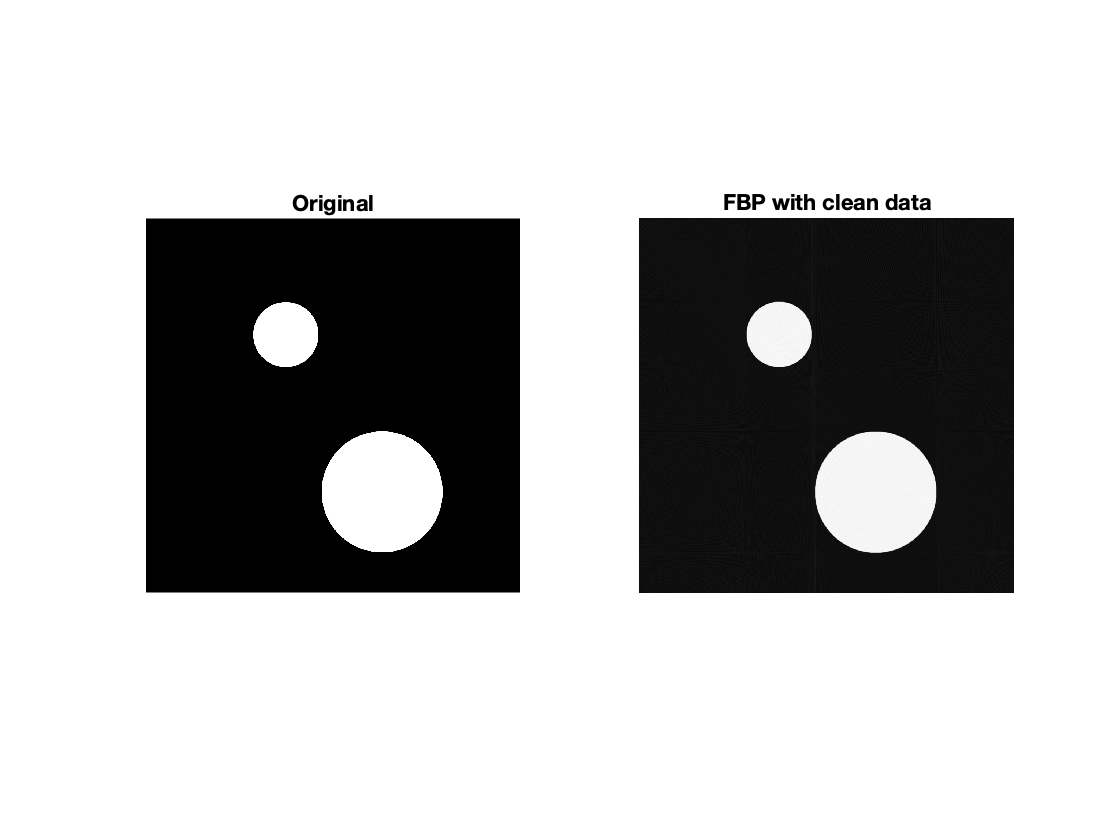

recon = iradon(sinogram,angvec,Nph);
% Take a look, comparing to original
figure
subplot(1,2,1)
imagesc(ph)
colormap gray
axis square
axis off
title('Original')
subplot(1,2,2)
imagesc(recon)
colormap gray
axis square
axis off
title('FBP with clean data')

print -dpng TwoDiscs_orig_n_FBP.png

Just for fun, remove the filter from FBP by inserting option 'none'.

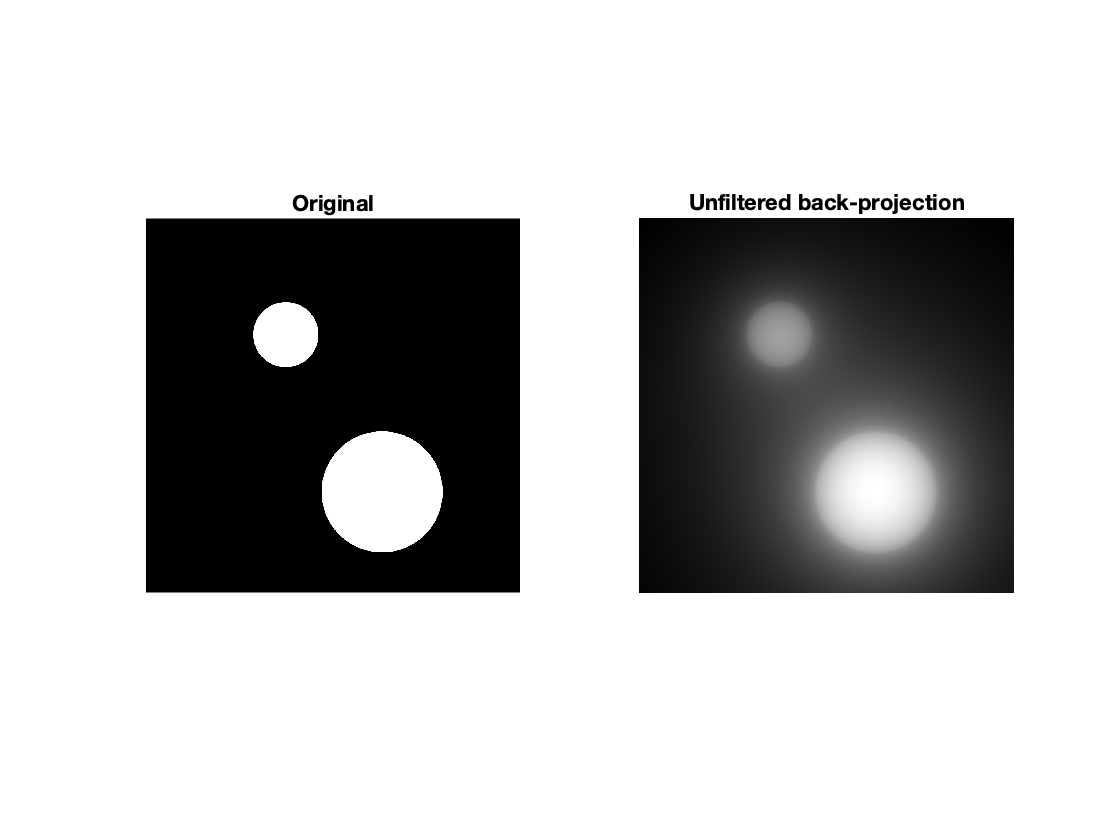

recon_BP = iradon(sinogram,angvec,'none',Nph);
% Take a look, comparing to original
figure
subplot(1,2,1)
imagesc(ph)
colormap gray
axis square
axis off
title('Original')
subplot(1,2,2)
imagesc(recon_BP)
colormap gray
axis square
axis off
title('Unfiltered back-projection')

We got a pretty much perfect reconstruction result above with FBP. But in practical measurements, the data will be noisy. We can simulate that by adding random numbers to the sinogram.

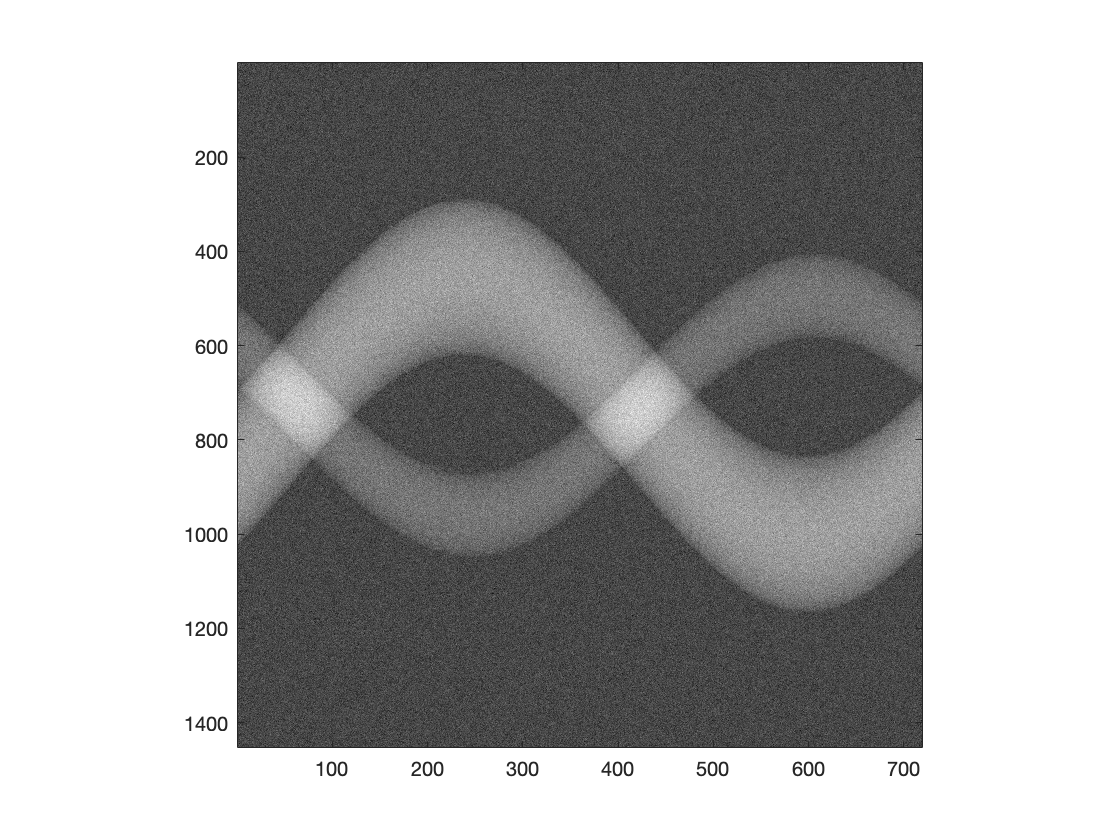

noise_amplitude = .1*max(abs(sinogram(:)));
sinogram_noisy = sinogram + ...
    noise_amplitude*randn(size(sinogram));
% Take a look
figure
imagesc(sinogram_noisy)
colormap gray
axis square

What happens when we reconstruct from noisy data?

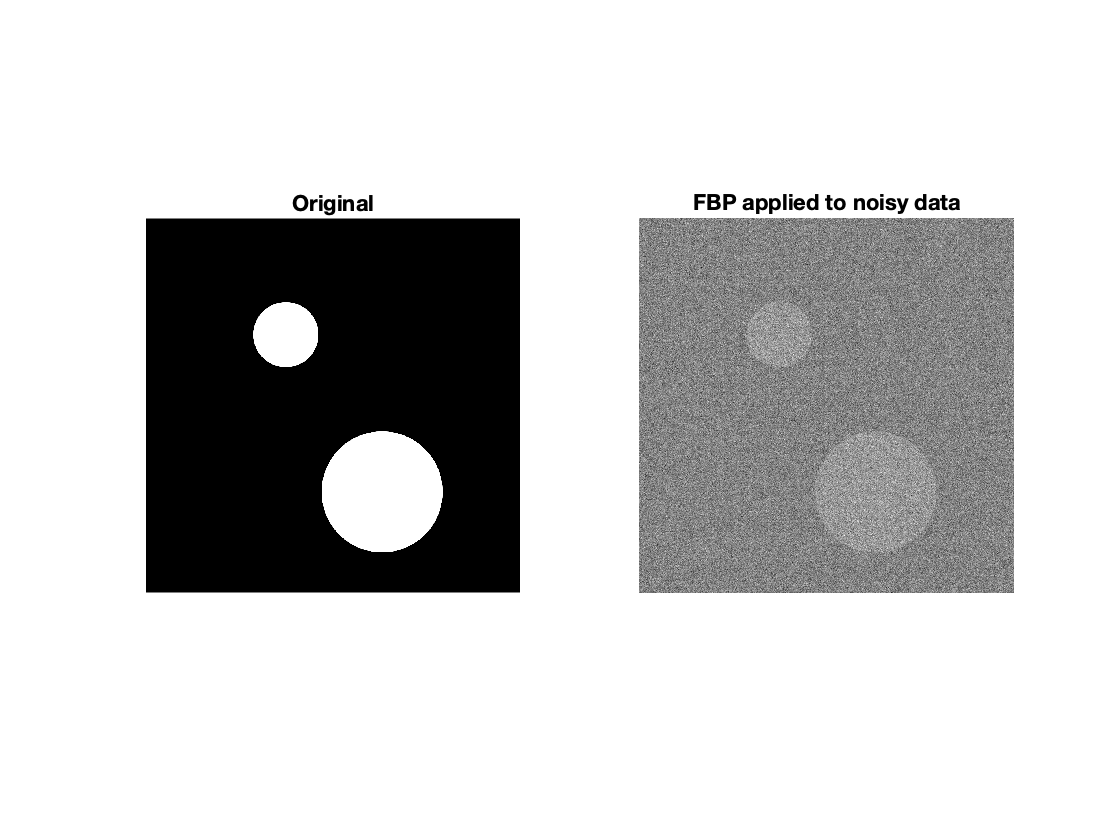

recon_noisy = iradon(sinogram_noisy,angvec,Nph);
% Take a look, comparing to original
figure
subplot(1,2,1)
imagesc(ph)
colormap gray
axis square
axis off
title('Original')
subplot(1,2,2)
imagesc(recon_noisy)
colormap gray
axis square
axis off
title('FBP applied to noisy data')

So we get quite a noisy result, which is not surprising. One way to reduce the effect of noise is modifying the filter in FBP. We can add another argument to iradon, setting frequency content to zero above the given cut-off frequency. 

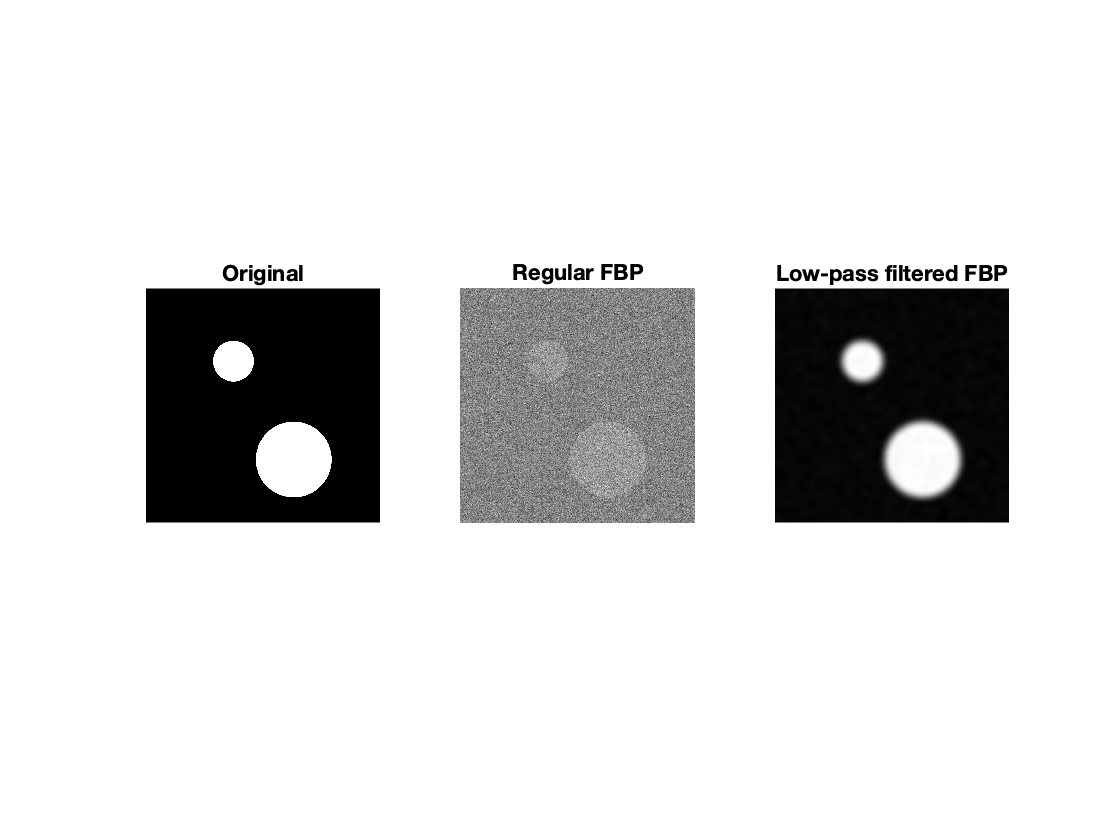

recon_noisy2 = iradon(sinogram_noisy,angvec,'hamming',.05,Nph);
% Take a look, comparing to original
figure
subplot(1,3,1)
imagesc(ph)
colormap gray
axis square
axis off
title('Original')
subplot(1,3,2)
imagesc(recon_noisy)
colormap gray
axis square
axis off
title('Regular FBP')
subplot(1,3,3)
imagesc(recon_noisy2)
colormap gray
axis square
axis off
title('Low-pass filtered FBP')